
%try replanner with 3 point lead
%i.e can only change the third point from current location
%then replan the ENTIRE path from the beginning, leave course correction to
%robot control (following)

%Try integral solution with a lower integral problem such as acceleration


clear
targets = [0,0; 50,100; 100,0];
pmin = 0;
pmax = 5;
pstep = 0.01;
FullMAT = PathPlanner(targets,pmin,pmax,pstep)

FullMAT = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0    0.0010       NaN    0.0010
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0020    0.0266    0.0010
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0030    0.0266    0.0010
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0004    0.0040    0.0266    0.0010
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0007    0.0050    0.0266    0.0010
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0012    0.0060    0.0266    0.0010
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0008    0.0017    0.0070    0.0266    0.0010
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

PosMAT = [FullMAT(:,1), FullMAT(:,2)];
VelMAT = [FullMAT(:,3), FullMAT(:,4)];
AccMAT = [FullMAT(:,5), FullMAT(:,6)];
JerkMAT = [FullMAT(:,7), FullMAT(:,8)];
SnapMAT = [FullMAT(:,9), FullMAT(:,10)];
BearingMAT = [FullMAT(:,11), FullMAT(:,12), FullMAT(:,13)];

%Pause not at t = 1/2 tmax to avoid any effects from symetry
%Pause/Interrupt
len = length(PosMAT);
Pauseloc = round(10/16*len);
Hold = [PosMAT(Pauseloc,:); VelMAT(Pauseloc,:); AccMAT(Pauseloc,:); JerkMAT(Pauseloc,:); SnapMAT(Pauseloc,:)]

Hold =    83.3378   27.8448
   41.1489  -55.3074
  -58.1837   12.1305
  -30.6115  324.4365
  278.8076 -634.8717


HoldRot = [BearingMAT(Pauseloc,:)]

HoldRot =   306.0000  143.3506    2.0000


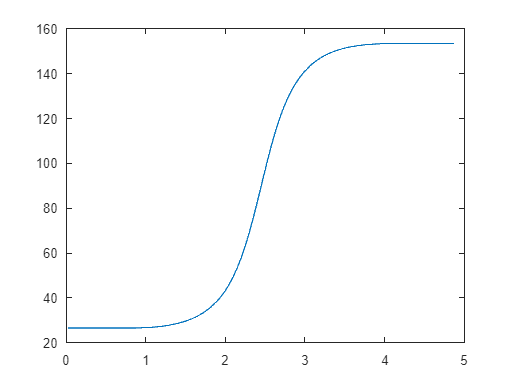

%New Target Entered
NewTarg = [120,40];
%Predictor Needs to know direction of motion
Radturn = 20;
Bearing = 2*pi*HoldRot(1,2)/360;
sect = HoldRot(1,3);
if sect == 1
    PredExt = [Radturn*sin(Bearing), Radturn*cos(Bearing)];
end
if sect == 2
    PredExt = [Radturn*sin(Bearing), Radturn*cos(Bearing)];
end
if sect == 3
    PredExt = [Radturn*sin(Bearing), Radturn*cos(Bearing)];
end
if sect == 4
    PredExt = [-Radturn*sin(Bearing), Radturn*cos(Bearing)];
end
Predictor = [(Hold(1,1) + PredExt(1,1)), (Hold(1,2)+PredExt(1,2))];
NewTargets = [Hold(1,1),Hold(1,2);...
    Hold(1,1),Hold(1,2);...
    Hold(1,1),Hold(1,2);...
    Hold(1,1),Hold(1,2);...
    Hold(1,1),Hold(1,2);...
    Predictor; NewTarg];
plot(BearingMAT(:,1)*pstep, BearingMAT(:,2));

plot(PosMAT(:,1), PosMAT(:,2))
hold on
scatter(NewTargets(:,1), NewTargets(:,2), 160, 'X', 'Color', "#A2142F")
xlabel('x direction')
ylabel('y direction')

%New Plan

pmin2 = Pauseloc*pstep;
pmax2 = pmax+3;
RePlanMAT = PathPlanner(NewTargets,pmin2, pmax2, pstep)

RePlanMAT =    83.3378   27.8448    0.0003   -0.0004    0.0067   -0.0089    0.1262   -0.1696    1.7944   -2.4118    1.0000  143.3506    2.0000
   83.3378   27.8448    0.0004   -0.0005    0.0080   -0.0108    0.1450   -0.1948    1.9686   -2.6460    2.0000  143.3506    2.0000
   83.3378   27.8448    0.0004   -0.0006    0.0096   -0.0128    0.1656   -0.2225    2.1509   -2.8909    3.0000  143.3506    2.0000
   83.3378   27.8448    0.0005   -0.0007    0.0113   -0.0152    0.1880   -0.2527    2.3412   -3.1467    4.0000  143.3506    2.0000
   83.3379   27.8448    0.0007   -0.0009    0.0133   -0.0179    0.2124   -0.2855    2.5396   -3.4134    5.0000  143.3506    2.0000
   83.3379   27.8448    0.0008   -0.0011    0.0156   -0.0209    0.2388   -0.3210    2.7460   -3.6909    6.0000  143.3506    2.0000
   83.3379   27.8448    0.0010   -0.0013    0.0181   -0.0243    0.2673   -0.3593    2.9606   -3.9793    7.0000  143.3506    2.0000
   83.3379   27.8447    0.0012   -0.0016    0.0209   -0.0281    0.2981 

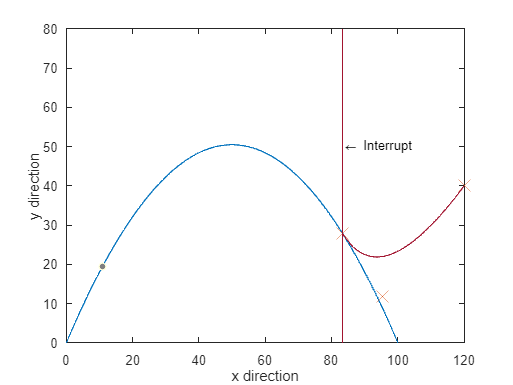

plot(RePlanMAT(:,1), RePlanMAT(:,2), 'Color', "#A2142F")
plot([RePlanMAT(1,1); RePlanMAT(1,1)], [0;80], 'Color', "#A2142F")
text(RePlanMAT(1,1), 50, '\leftarrow Interrupt', 'HorizontalAlignment', 'Left')
hold off

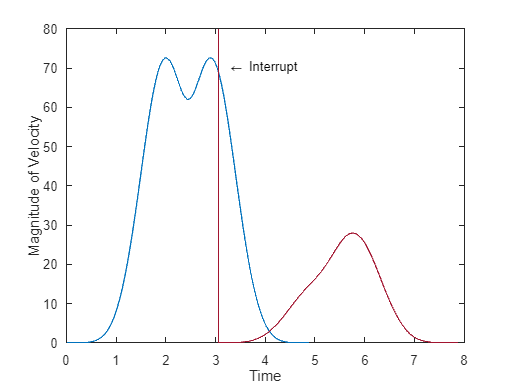


VMagMAT = absBS(VelMAT);
reVMagMAT = absBS(RePlanMAT(:,3:4));
plot(VMagMAT(:,1)*pstep, VMagMAT(:,2))
hold on
plot(reVMagMAT(:,1)*pstep+Pauseloc*pstep, reVMagMAT(:,2), 'Color', "#A2142F")
plot([Pauseloc*pstep; Pauseloc*pstep], [0;80], 'Color', "#A2142F")
xlabel('Time')
ylabel('Magnitude of Velocity')
text(Pauseloc*pstep, 70, ' \leftarrow Interrupt', 'HorizontalAlignment', 'Left')

function FullMAT = PathPlanner(targets, pmin, pmax ,pstep)
    order = 7;
    CP = points(targets, order);
    CPx = CP(:,1);
    CPy = CP(:,2);
    %Knot Vector
    knot = knotvect(CP, order, pmin, pmax, pstep);
    ksz = size(knot);
    validpmin = knot(1, order);
    validpmax = knot(1, (ksz(1,2)-order+1));
    NK2MAT = [];
    NK3MAT = [];
    NK4MAT = [];
    NK5MAT = [];
    NK6MAT = [];
    NK7MAT = [];
    pM1 = [];
    pM2 = [];
    pM3 = [];
    pM4 = [];
    pM5 = [];
    pM6 = [];
    %Initial Path Plan
    PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
    order = 6;
    CP = DCP(CP, knot, order);
    knot = Dkn(knot);
    VelMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
    order = 5;
    CP = DCP(CP, knot, order);
    knot = Dkn(knot);
    AccMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
    order = 4;
    CP = DCP(CP, knot, order);
    knot = Dkn(knot);
    JerkMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
    order = 3;
    CP = DCP(CP, knot, order);
    knot = Dkn(knot);
    SnapMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
    BearingMAT = direc(VelMAT);

    %Load all data into matrix for function return
    FullMAT = [PosMAT, VelMAT, AccMAT, JerkMAT, SnapMAT, BearingMAT];
end
function pMAT = pMAT(p,knot,k)
        N = length(knot);
        pMAT = [];
        for i = 1:1:N-k
            pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
            pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
            Head = zeros(i-1,1);
            Foot = zeros(N-k-i,1);
            pvect = [Head; pconst1; pconst2; Foot];
            pMAT = [pMAT, pvect];
        end
    end
    function CP = points(targets, order)
        P = height(targets);
        rep = order - 1;
        CP = [];
        hold = [targets(1,1), targets(1,2)];
        for n = 1:1:rep
            CP = [CP; hold];
        end
        for i = 2:1:P-1
            hold = [targets(i,1), targets(i,2)];
            CP = [CP; hold];
        end
        hold = [targets(P,1), targets(P,2)];
        for k = 1:1:rep
            CP = [CP; hold];
        end
    end
    function Knot = knotvect(CP, order, pmin, pmax, pstep)
        sz = size(CP);
        P = sz(1,1);
        K = P + order;
        Knot = pmin;
        for i = 1:1:order-1
            Knot = [Knot, pmin+i*pstep];
        end
        for i = 1:1:K-2*order
            Knot = [Knot, i*pmax/(K-2*order+1)];
        end
        for i = 1:1:order
            Knot = [Knot, pmax-(order-i)*pstep];
        end
    end
    function NK1MAT = NK1MAT(p, knot)
        N = length(knot);
        NK1MAT = [];
        for i = 1:1:N-1
            lowkn = knot(i);
            highkn = knot(i+1);
            if lowkn<=p && p<highkn
                NK1MAT = [NK1MAT, 1];
            else
                NK1MAT = [NK1MAT, 0];
            end
        end
    end
    
    function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
        BSplineMAT = [];
        for p = pmin:pstep:pmax
            if p >= validpmin
                if p<=validpmax
                    k = 2;
                    NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                    k = 3;
                    NK3MAT = NK2MAT*pMAT(p, knot, k);
                    k = 4;
                    if order < k
                        Pos = NK3MAT*CP;
                    else
                        NK4MAT = NK3MAT*pMAT(p, knot, k);
                        k = 5;
                        if order < k
                            Pos = NK4MAT*CP;
                        else
                            NK5MAT = NK4MAT*pMAT(p, knot, k);
                            k = 6;
                            if order < k
                                Pos = NK5MAT*CP;
                            else
                                NK6MAT = NK5MAT*pMAT(p, knot, k);
                                k = 7;
                                if order < k
                                    Pos = NK6MAT*CP;
                                else
                                    NK7MAT = NK6MAT*pMAT(p, knot, k);
                                    Pos = NK7MAT*CP;
                                end
                            end
                        end
                    end
                    BSplineMAT = [BSplineMAT; Pos];
                end
            end
        end
    end
    
    function DP = DCP(CP, knot, k)
        n = length(CP);
        DP = [];
        for i = 1:1:n-1
            I = i+1;
            P1 = [CP(i,1),CP(i,2)];
            P2 = [CP(i+1,1),CP(i+1,2)];
            DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
            DP = [DP; DPnew];
        end
    end
    function DKnot = Dkn(knot)
        N = length(knot);
        DKnot = [];
        for i = 1:1:N-2
            DKnew = knot(i+1);
            DKnot = [DKnot, DKnew];
        end
    end
    function MagMAT = absBS(Pos)
        N = length(Pos.');
        MagMAT = [];
        for i = 1:1:N
            X = Pos(i,1);
            Y = Pos(i,2);
            abs = sqrt(X^2+Y^2);
            MagMAT = [MagMAT; i, abs];
        end
    end
    function bearingMAT = direc(Vel)
        N = length(Vel.');
        bearingMAT = [];
        for i = 1:1:N
            X = Vel(i,1);
            Y = Vel(i,2);
            vtan = (360*atan(X/Y))/(2*pi);
            if X >= 0 && Y >= 0
                dir = vtan;
                sect = 1;
            end
            if X >= 0 && Y < 0
                dir = 180 + vtan;
                sect = 2;
            end
            if X < 0 && Y >= 0
                dir = 360 + vtan;
                sect = 3;
            end
            if X < 0 && Y < 0
                dir = 180 + vtan;
                sect = 4;
            end
            bearingMAT = [bearingMAT; i, dir, sect];
        end
    end